## Zestaw 5

Ad 1

    Generowanie losowej sieci przepływowej o N warstwach

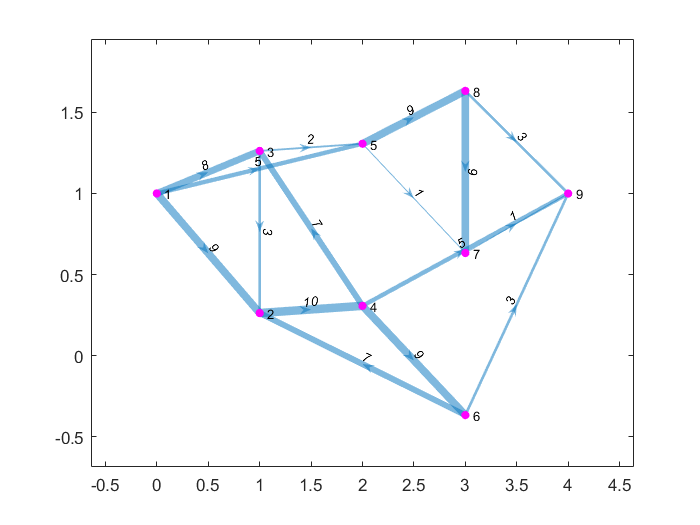

clear; close all; clc;

N = 3;
net = Flownet(N);
plot(net);

Ad 2

     Wyznaczanie maksymalnego przepływu dla wylosowanej sieci

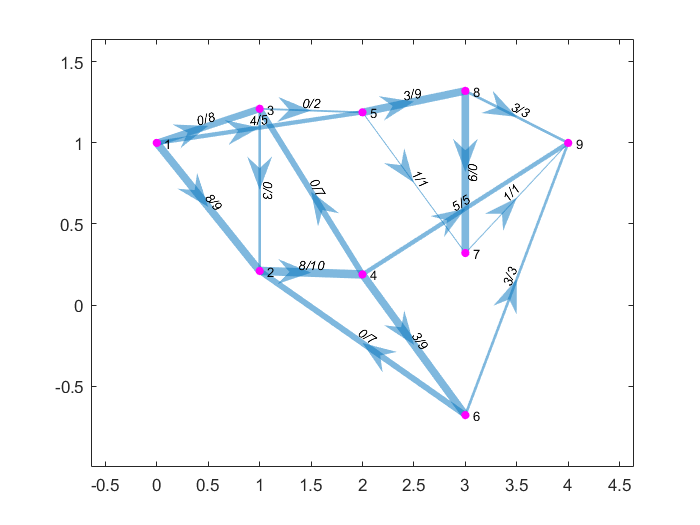

[f, resnet] = fordfulkerson(net, 1, length(net.Nodes));


labels =  f + "/" + net.Edges(3,:);
n = length(net.Nodes);
x = zeros(1, n);
y = zeros(1, n);
middle = length(net.Layers{1})/2;
y(1) = middle;
y(n) = middle;
x(n) = net.NumberOfLayers+1;
lastid = 2;
for i=1:net.NumberOfLayers
    npl = length(net.Layers{i});
    offset = middle-npl/2+rand()-0.5;
    x(lastid:lastid+npl-1) = i;
    for j=1:npl
        y(lastid) = offset + (j-1);
        lastid = lastid + 1;
    end
end
d = net.getDigraph();
LWidths = (5*d.Edges.Weight+1)/max(d.Edges.Weight);
plot(d,'NodeColor','m','EdgeLabel',labels,'LineWidth',LWidths, 'XData', x, 'YData', y, 'ArrowSize', 20);

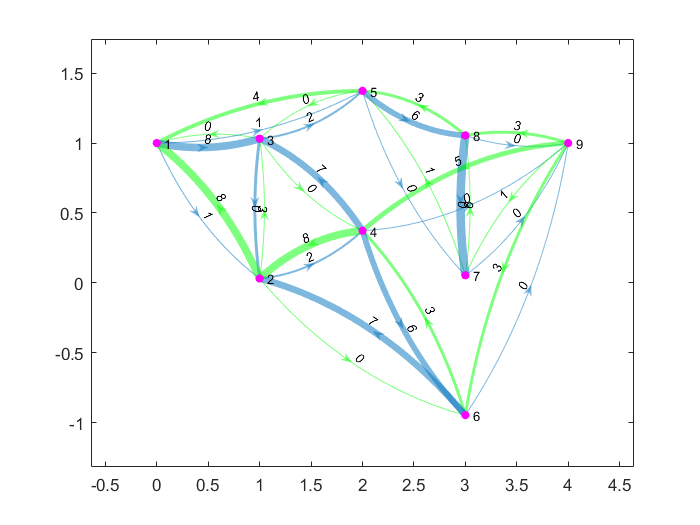

plot(resnet);